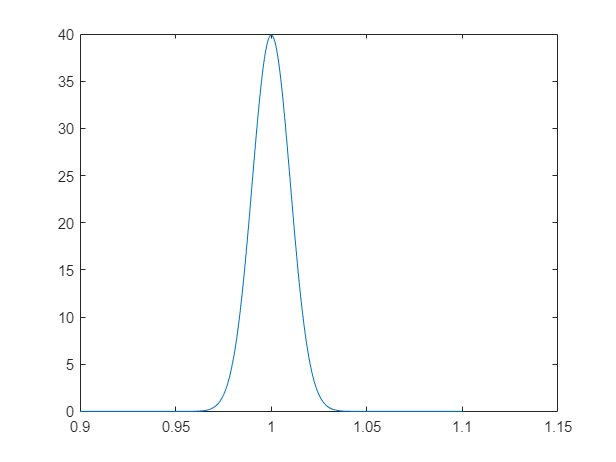

clear 
close all

radiusDist = makedist("Normal","mu",1.0,"sigma",0.01);
stiffnessDist = makedist("Normal","mu",29e6,"sigma",1e6);
poissonDist = makedist("Normal","mu",0.25,"sigma",0.1);

figure
radius = linspace(0.9,1.1,1e5);
plot(radius, pdf(radiusDist,radius))

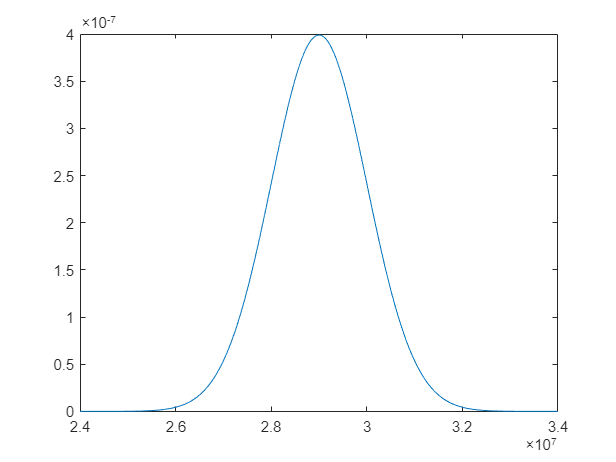


figure
stiffness = linspace(24e6,34e6,1e5);
plot(stiffness, pdf(stiffnessDist,stiffness))

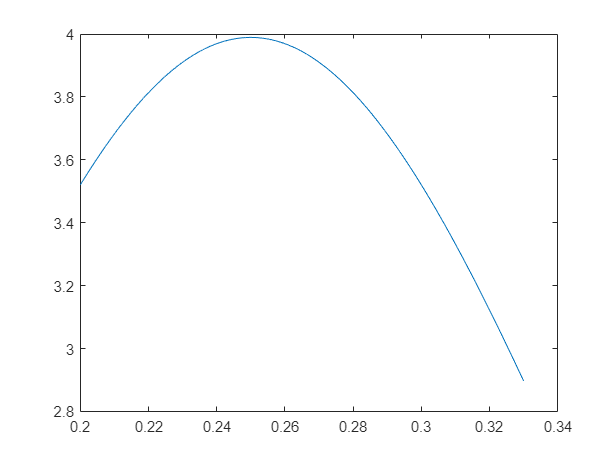


figure
poisson = linspace(0.2,0.33,1e5);
plot(poisson, pdf(poissonDist,poisson))

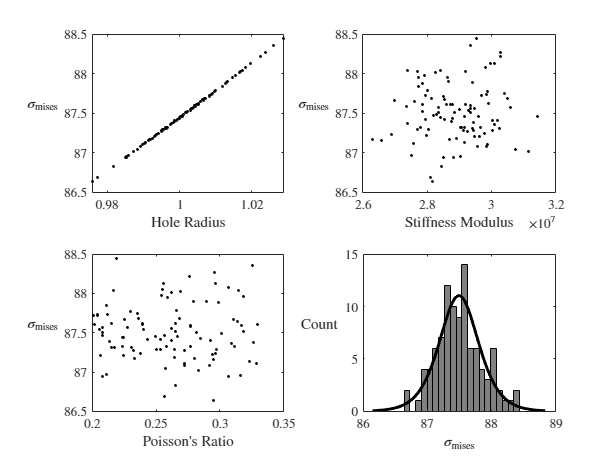

clear

filename = "PWH_monte_carlo_results.csv";
[radius, stiffness, poisson, max_mises] = importfile(filename);

subplot(2,2,1)
scatter(radius, max_mises, '.k')
xlabel("Hole Radius", Interpreter="latex")
ylabel("$$\sigma_{\textrm{mises}}$$", Interpreter="latex", Rotation=0, HorizontalAlignment="right")
ax = gca;
ax.Box = "on";
ax.TickLabelInterpreter = "latex";

subplot(2,2,2)
scatter(stiffness, max_mises, '.k')
xlabel("Stiffness Modulus", Interpreter="latex")
ylabel("$$\sigma_{\textrm{mises}}$$", Interpreter="latex", Rotation=0, HorizontalAlignment="right")
ax = gca;
ax.Box = "on";
ax.TickLabelInterpreter = "latex";

subplot(2,2,3)
scatter(poisson, max_mises, '.k')
xlabel("Poisson's Ratio", Interpreter="latex")
ylabel("$$\sigma_{\textrm{mises}}$$", Interpreter="latex", Rotation=0, HorizontalAlignment="right")
ax = gca;
ax.Box = "on";
ax.TickLabelInterpreter = "latex";

subplot(2,2,4)
h = histfit(max_mises,20,"logistic");
h(1).EdgeColor = [0 0 0];
h(1).FaceColor = [0.5 0.5 0.5];
h(2).Color = [0 0 0];
% histogram(max_mises,20, EdgeColor="black", FaceColor="black")
xlabel("$$\sigma_{\textrm{mises}}$$", Interpreter="latex")
ylabel("Count", Interpreter="latex", Rotation=0, HorizontalAlignment="right")
ax = gca;
ax.Box = "on";
ax.TickLabelInterpreter = "latex";

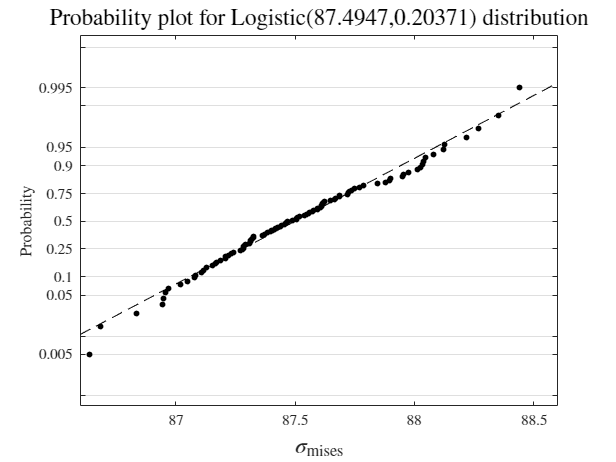


figure
prob = fitdist(max_mises, "Logistic");
h = probplot(prob, max_mises);
h(1).Color = "black";
h(1).Marker = ".";
h(1).MarkerSize = 12;
h(2).Color = "black";
% h(3).Color = "black";


ax = gca;
xlabel("$$\sigma_{\textrm{mises}}$$", Interpreter="latex", FontSize=16)
ax.YLabel.Interpreter = "latex";
ax.Title.Interpreter = "latex";
ax.Title.FontSize = 16;
ax.Box = "on";
ax.TickLabelInterpreter = "latex";
ax.YGrid = "on";

function [radius, stiffness, poisson, max_mises] = importfile(filename)
%IMPORTFILE Import data from a text file
%  [RADIUS, STIFFNESS, POISSON, MAX_MISES] = IMPORTFILE(FILENAME) reads
% Auto-generated by MATLAB on 21-Oct-2021 23:49:19

%% Input handling

% If dataLines is not specified, define defaults
dataLines = [2, Inf];

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 4);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["radius", "stiffness", "poisson", "max_mises"];
opts.VariableTypes = ["double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
tbl = readtable(filename, opts);

%% Convert to output type
radius = tbl.radius;
stiffness = tbl.stiffness;
poisson = tbl.poisson;
max_mises = tbl.max_mises;
end